## Definición de Problema

clear;
CostFunction = @(x) sum(x.^2, 2);       % Función de costo a optimizar
VarDims = 2;                            % No. Variables desconocidas (Varibles de decisión). Dims de posición de partículas

PosMin = -10;                           % Límite inferior para el valor de las variables desconocidas
PosMax = 10;                            % Límite superior para el valor de las variables desconocidas.

VelMax = 0.2*(PosMax - PosMin);
VelMin = -VelMax;

[MeshX, MeshY] = meshgrid(PosMin:PosMax, PosMin:PosMax);
Mesh2D = [reshape(MeshX, [], 1) reshape(MeshY, [], 1)];
Altura = reshape(CostFunction(Mesh2D), size(MeshX, 1), size(MeshX, 2));
MaxAltura = max(max(Altura));

X1_min = min(min(Altura,[],2));
X2_min = min(min(Altura,[], 1));
Coords_Min = [X1_min X2_min];

AreaTotal = (PosMax - PosMin)^2;
Porcentaje_AreaTotal = 0.1;
RadioConvergencia = sqrt((AreaTotal * (Porcentaje_AreaTotal/100)) / pi); 


## Parámetros PSO

NoParticulas = 50;                              % No. de partículas
Colores = (1: NoParticulas) / NoParticulas;     % Vector con los colores de cada punto

% Coeficientes de Constricción
Kappa = 1;
Phi1 = 2.05;
Phi2 = 2.05;
Phi = Phi1 + Phi2;
Chi = 2*Kappa / abs(2 - Phi - sqrt(Phi^2 - 4*Phi));

% La implementación original del PSO sugiere
% valores iniciales para cada una de estas variables

W = Chi;                    % Coeficiente de inercia.
WDamp = 1;                  % Coeficiente de amortiguamiento del coeficiente inercial
C1 = Chi*Phi1;              % Coeficiente de aceleración local (Personal)
C2 = Chi*Phi2;              % Coeficiente de aceleración global

Intervalo = 50;
VecKappa = 0 : Kappa*2 / (Intervalo-1)  : Kappa*2;
VecPhi1 = 0 : Phi1*2 / (Intervalo-1) : Phi1*2;
VecPhi2 = 0 : Phi2*2 / (Intervalo-1) : Phi2*2;

[MatPhi1, MatPhi2, MatKappa] = meshgrid(VecPhi1, VecPhi2, VecKappa);
MatPhi1 = reshape(MatPhi1,[], 1);
MatPhi2 = reshape(MatPhi2,[], 1);
MatKappa = reshape(MatKappa, [], 1);

Points = size(MatKappa, 1);

## Inicialización

% Estructura que contiene las diferentes propiedades de una partícula
IteracionesMax = 3000;
Posicion_Actual = unifrnd(PosMin, PosMax, [NoParticulas VarDims]);      % Posición (Random) de todas las partículas. Distribución uniforme.     Dims: NoParticulas X VarDims
Posicion_LocalBest = Posicion_Actual;                                   % Las posiciones que generaron los mejores costos en las partículas     Dims: NoParticulas X VarDims
Velocidad = zeros([NoParticulas VarDims]);                              % Velocidad de todas las partículas. Inicialmente 0.                    Dims: NoParticulas X VarDims
Costo_Local = CostFunction(Posicion_Actual);                            % Evaluación del costo en la posición actual de la partícula.           Dims: NoPartículas X 1 (Vector Columna)
Costo_LocalBest = Costo_Local;

[Costo_GlobalBest, Fila] = min(Costo_LocalBest);                        % "Global best": El costo más pequeño del vector "CostoLocal"           Dims: Escalar
Posicion_GlobalBest = Posicion_Actual(Fila, :);                         % "Global best": Posición que genera el costo más pequeño               Dims: 1 X VarDims

Costo_History = zeros([IteracionesMax 1]);                              % Historial de todos los "Costo_Global" o global best
Costo_History(1) = Costo_GlobalBest;                                    % La primera posición del vector es el primer "Global Best"

## Main Loop

ModoVisualizacion = "None";                                             % Modo de visualización: 2D, 3D o None. Si se ingresa algo no válido se toma una visualización 3D como default
Iteraciones = 0;

Iteraciones_History = zeros(Points,1);

if strcmp(ModoVisualizacion, "None") == 0
    figure(1); clf;
    figure('visible','on');
    axis equal; grid on; 
    
    FigureWidth = 900;
    FigureHeight = 400;
    ScreenSize = get(0,'ScreenSize');
    set(gcf, 'Position',  [ScreenSize(3)/2 - FigureWidth/2, ScreenSize(4)/2 - FigureHeight/2, FigureWidth, FigureHeight])
end

for j = 1:Points
    
    Phi1 = MatPhi1(j);
    Phi2 = MatPhi2(j);
    Kappa = MatKappa(j);
    
    Phi = Phi1 + Phi2;
    Chi = 2*Kappa / abs(2 - Phi - sqrt(Phi^2 - 4*Phi));

    W = Chi;                    % Coeficiente de inercia.
    WDamp = 1;                  % Coeficiente de amortiguamiento del coeficiente inercial
    C1 = Chi*Phi1;              % Coeficiente de aceleración local (Personal)
    C2 = Chi*Phi2;              % Coeficiente de aceleración global
    
    IteracionesMax = 3000;
    Iteraciones = 0;
    
    for i = 2:IteracionesMax
        
        R1 = rand([NoParticulas VarDims]);
        R2 = rand([NoParticulas VarDims]);
        
        % Actualización de Velocidad
        Velocidad = W * Velocidad ...                                                   % Término inercial
            + C1 * R1 .* (Posicion_LocalBest - Posicion_Actual) ...                     % Componente cognitivo
            + C2 * R2 .* (Posicion_GlobalBest - Posicion_Actual);                       % Componente social
        
        Velocidad = max(Velocidad, VelMin);                                             % Se truncan los valores de velocidad en el valor mínimo y máximo
        Velocidad = min(Velocidad, VelMax);
        
        % Actualización de Posición
        Posicion_Actual = Posicion_Actual + Velocidad;
        Posicion_Actual = max(Posicion_Actual, PosMin);                                 % Se truncan los valores de posición en el valor mínimo y máximo
        Posicion_Actual = min(Posicion_Actual, PosMax);
        
        % Actualización de Local y Global Best
        Costo_Local = CostFunction(Posicion_Actual);                                    % Actualización de los valores del costo
        Costo_LocalBest = min(Costo_LocalBest, Costo_Local);                            % Se sustituyen los costos que son menores al "Local Best" previo
        Costo_Change = (Costo_Local < Costo_LocalBest);                                 % Vector binario que indica con un 0 cuales son las filas de "Costo_Local" que son menores que las filas de "Costo_LocalBest"
        Posicion_LocalBest = Posicion_LocalBest .* Costo_Change + Posicion_Actual;      % Se sustituyen las posiciones correspondientes a los costos a cambiar en la linea previa
        
        [Costo_Global, Fila] = min(Costo_LocalBest);                                    % Valor mínimo de entre los valores de "Costo_Local"
        
        if Costo_Global < Costo_GlobalBest                                              % Si el nuevo costo global es menor al "Global Best" entonces
            Costo_GlobalBest = Costo_Global;                                            % Se actualiza el valor del "Global Best"
            Posicion_GlobalBest = Posicion_Actual(Fila, :);                             % Y la posición correspondiente al "Global Best"
        end
        
        % Actualización del historial de "Best Costs"
        Costo_History(i) = Costo_GlobalBest;                                            
        
        % Actualización del coeficiente inercial
        W = W * WDamp;
        
        % Actualizar el número de iteraciones
        Iteraciones = Iteraciones + 1;
        
        if strcmp(ModoVisualizacion, "None") == 0
            
            % Graficación de partículas
            subplot(1, 2, 2); cla;
            
            if strcmp(ModoVisualizacion, "2D")
                axis([PosMin PosMax PosMin PosMax]);
                contour(MeshX, MeshY, Altura);
                alpha 0.5;
                scatter(Posicion_Actual(:,1), Posicion_Actual(:,2), 10, Colores, 'filled');
                scatter(X1_min, X2_min, 'red', 'x');
                viscircles([X1_min X2_min], RadioConvergencia);
            else
                axis([PosMin PosMax PosMin PosMax 0 MaxAltura]);
                surf(MeshX, MeshY, Altura);
                shading interp
                alpha 0.5;
                scatter3(Posicion_Actual(:,1), Posicion_Actual(:,2), Costo_Local, [], Colores, 'filled');
            end
            title({"Partículas"; strcat("Radio Convergencia: ", num2str(RadioConvergencia), " (", num2str(Porcentaje_AreaTotal), "%)")});
            hold on;
            
            % Graficación de función de costo
            subplot(1, 2, 1); cla;
            plot(Costo_History(1:i), 'LineWidth', 2);
            title({"Minimización de Función de Costo" ; strcat("Iteraciones Actuales: ", num2str(i))})
            xlabel('Iteración');
            ylabel('Costo Óptimo');
            
        end
        
        % Criterio de finalización
        Distancia_ParticulaMasLejana = max(sqrt(sum((Posicion_Actual - Coords_Min).^2, 2)));
        
        if Distancia_ParticulaMasLejana < RadioConvergencia
            Iteraciones = i;
            
            if strcmp(ModoVisualizacion, "None") == 0
                title({"Minimización de Función de Costo" ; strcat("Iteraciones para Converger: ", num2str(Iteraciones))});
            else
                %disp("Proceso Finalizado")
            end
            
            break
        end
        
        if i == IteracionesMax
            Iteraciones = IteracionesMax;
        end
         
        drawnow
         
    end
    
    Iteraciones_History(j) = Iteraciones;
    
end

disp("Proceso Finalizado")

Proceso Finalizado


Investigar:

Artificial potential fields

Robots móviles, que se utiliza para esquivar obstáculos (Braitenberg vehicles)

Generar una función de costo sin conocer completamente el 

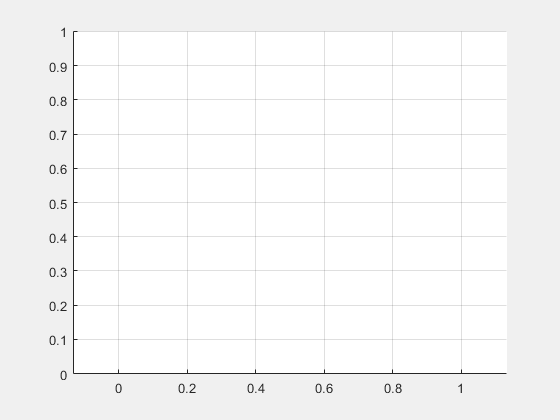

Error using scatter3 (line 135)
Error setting property 'MarkerFaceAlpha' of class 'Scatter':
Value not a numeric scalar

load Iteraciones.mat
IteracionesMax = 3000;

Iteraciones_HistoryNorm = 1 - (Iteraciones_History/IteracionesMax);

figure(2); clf;
figure('visible','on');
axis equal; grid on;
hold on
scatter3(MatPhi1, MatPhi2, MatKappa)


% for i = 2:size(Iteraciones_History,1)
% 
%     scatter3(MatPhi1(i), MatPhi2(i), MatKappa(i),'MarkerFaceAlpha',Iteraciones_HistoryNorm(i));
%     
% end
% 
% title("Iteraciones Requeridas para Converger según parámetros Kappa, Phi1 y Phi2")
% xlabel('Phi1');
% ylabel('Phi2');
% zlabel("Kappa");

% imshow
